% looks like blue dots are 1st msec, red are 2nd
% (:,4) is the 2nd measured msec (inverted to account for the switch it
% polarity
% (:,3) is the 1st measured msec)
% (:,6) is the theory 

% get a clean workspace, make sure data is loaded
close all



## My function to plot this - requires statistics toolbox i believe 

function [curve1_1st,gof1_1st,curve1_2nd,gof1_2nd] = scatterplot_func(d1)  

s = inputname(1);

%scatter with linear fit 

figure;plot(d1(:,3),d1(:,6),'bo')

hold on;plot(-d1(:,4),d1(:,6),'ro')

xlim([-.6 .6])

ylim([-.6 .6])

[curve1_1st,gof1_1st] = fit(d1(:,3),d1(:,6),'poly1','Exclude', isnan(d1(:,3)),'Exclude',isnan(d1(:,6)))

[curve1_2nd,gof1_2nd] = fit(-d1(:,4),d1(:,6),'poly1','Exclude', isnan(d1(:,4)),'Exclude',isnan(d1(:,6)))

a = plot(curve1_1st,'b');

a.LineWidth = 2;

b = plot(curve1_2nd,'r');

b.LineWidth = 2;

x = [-0.6 0.6];

y = [-0.6 0.6];

plot(x,y,'k','linewidth',2)

legend({'1st part of pulse','2nd part of pulse','1st part fit','2nd part fit','line of y = x'},'Location','northwest')

xlabel('Measured voltage (V)')

ylabel('Theoretical Voltage (V)')

title({s,' theory vs. experiment'})

% scatterhist 

figure;

exp =  [d1(:,3);-d1(:,4)];

theory = [d1(:,6);d1(:,6)];

groups = cell(128,1);

groups(1:64) = {'1st'};

groups(65:end) = {'2nd'};

scatterhist(exp,theory,'Group',groups,'PlotGroup','on','Color','br','LineWidth',[2,2],'kernel','on')

xlabel('Measured voltage (V)')

ylabel('Theoretical Voltage (V)')

title({s,' theory vs. experiment'})

end

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.064  (0.9704, 1.157)
       p2 =    0.004107  (-0.008208, 0.01642)

gof1_1st =            sse: 0.1393
       rsquare: 0.8965
           dfe: 60
    adjrsquare: 0.8948
          rmse: 0.0482


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.069  (0.976, 1.161)
       p2 =     0.00353  (-0.008648, 0.01571)

gof1_2nd =            sse: 0.1364
       rsquare: 0.8987
           dfe: 60
    adjrsquare: 0.8970
          rmse: 0.0477


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.064  (0.9704, 1.157)
       p2 =    0.004107  (-0.008208, 0.01642)

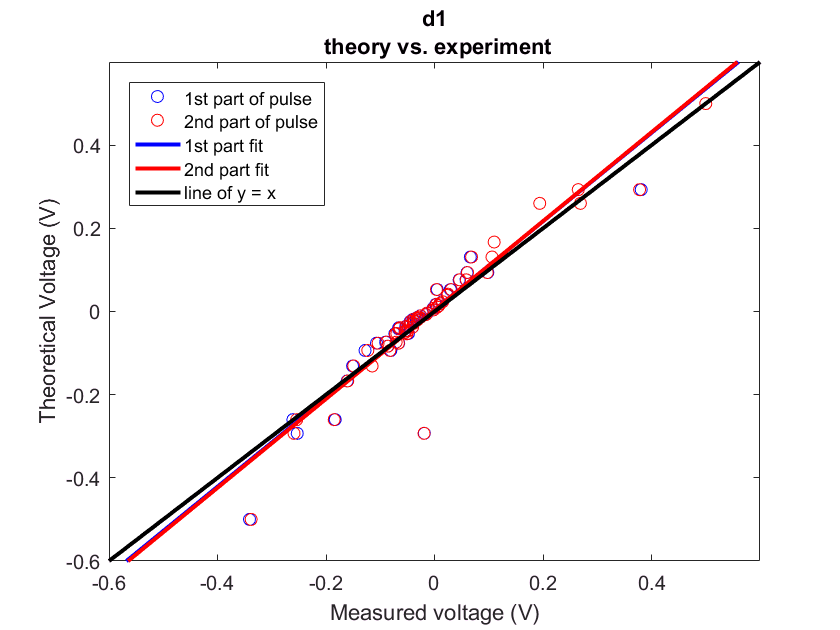

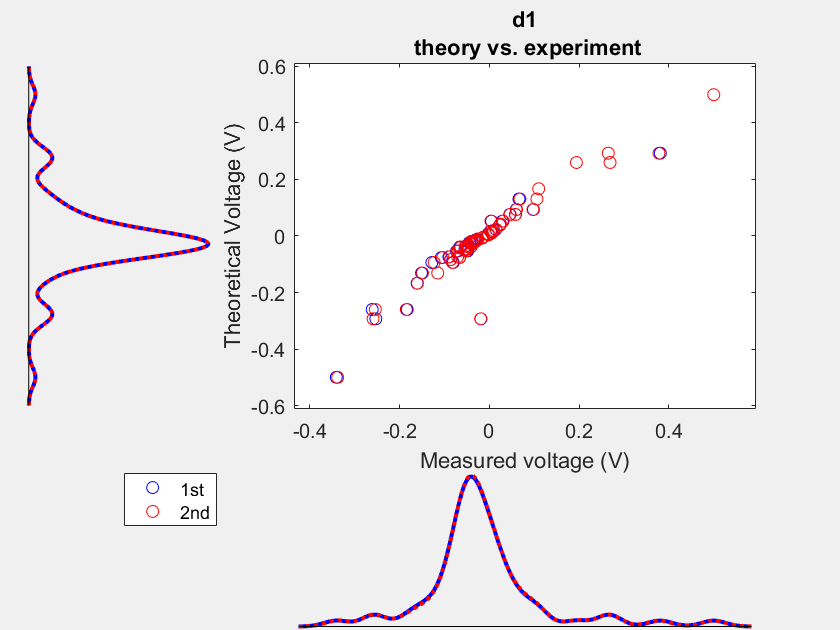


scatterplot_func(d1)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.042  (1.007, 1.078)
       p2 =     0.01338  (0.008407, 0.01836)

gof1_1st =            sse: 0.0224
       rsquare: 0.9829
           dfe: 60
    adjrsquare: 0.9826
          rmse: 0.0193


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.015  (0.9816, 1.048)
       p2 =     0.01536  (0.01057, 0.02015)

gof1_2nd =            sse: 0.0207
       rsquare: 0.9842
           dfe: 60
    adjrsquare: 0.9840
          rmse: 0.0186


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.042  (1.007, 1.078)
       p2 =     0.01338  (0.008407, 0.01836)

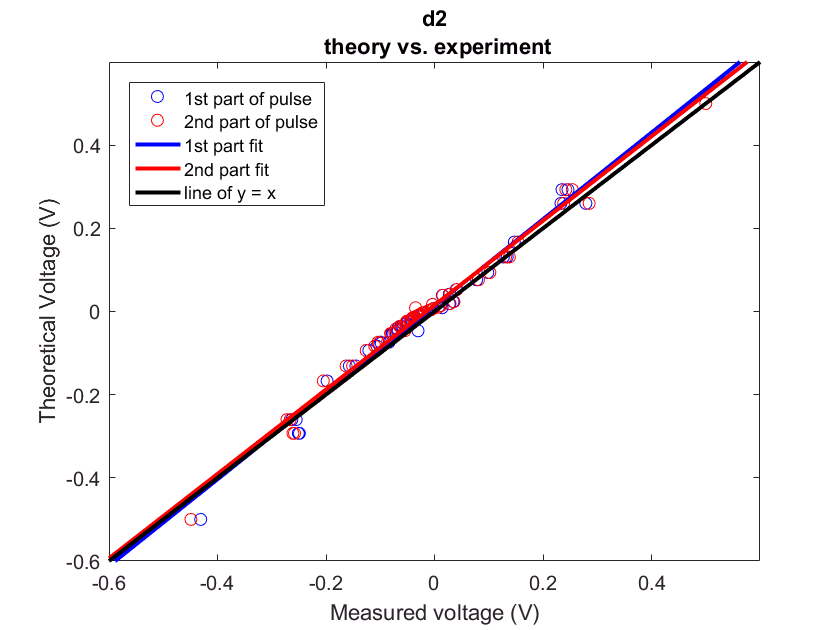

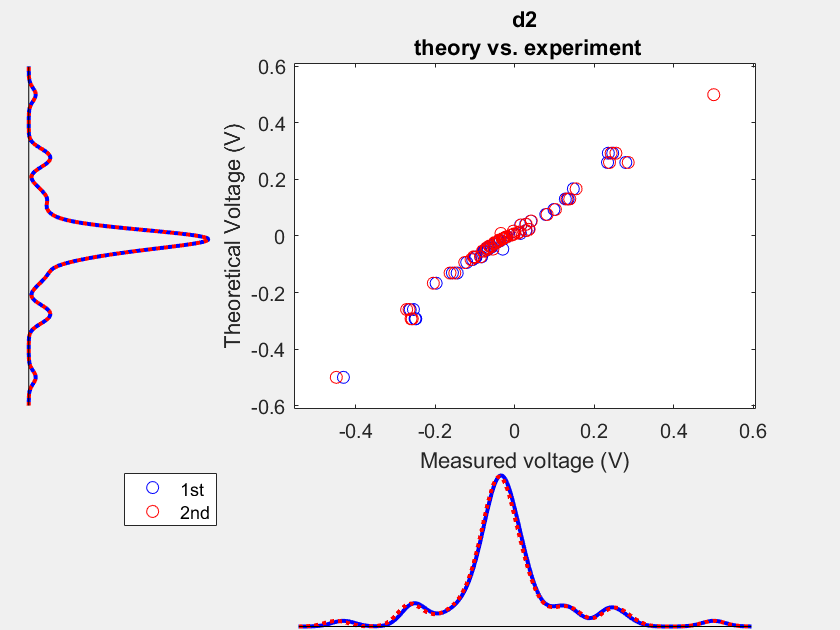

scatterplot_func(d2)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9759  (0.9214, 1.03)
       p2 =     0.02118  (0.01418, 0.02818)

gof1_1st =            sse: 0.0431
       rsquare: 0.9553
           dfe: 60
    adjrsquare: 0.9545
          rmse: 0.0268


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       0.975  (0.9227, 1.027)
       p2 =     0.02068  (0.01397, 0.0274)

gof1_2nd =            sse: 0.0397
       rsquare: 0.9588
           dfe: 60
    adjrsquare: 0.9581
          rmse: 0.0257


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9759  (0.9214, 1.03)
       p2 =     0.02118  (0.01418, 0.02818)

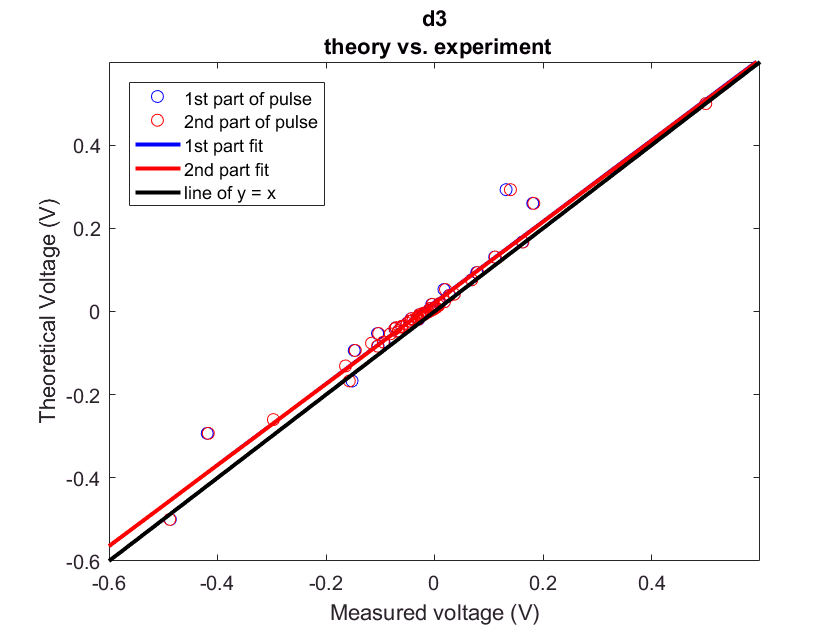

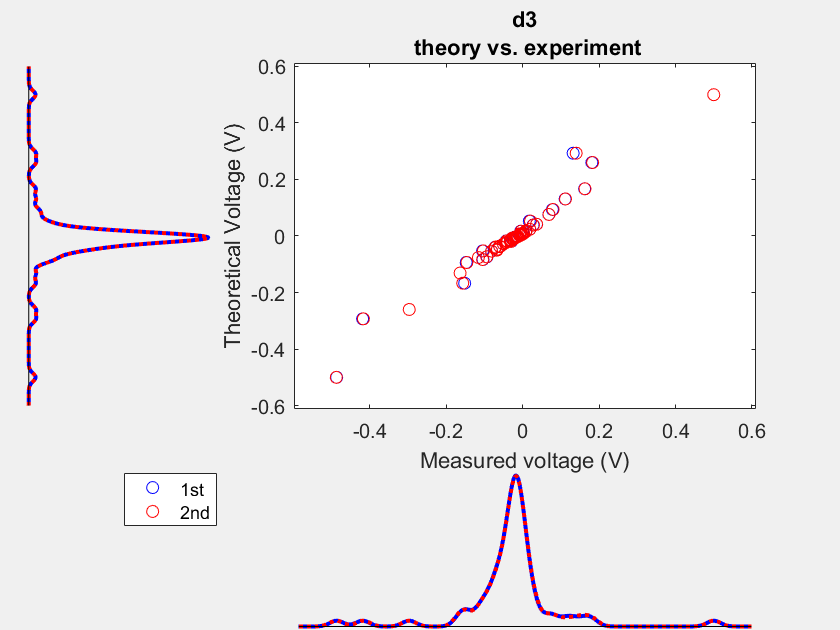

scatterplot_func(d3)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9872  (0.8783, 1.096)
       p2 =   0.0002869  (-0.0145, 0.01508)

gof1_1st =            sse: 0.2022
       rsquare: 0.8455
           dfe: 60
    adjrsquare: 0.8430
          rmse: 0.0581


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        1.02  (0.9114, 1.128)
       p2 =   0.0001723  (-0.01415, 0.01449)

gof1_2nd =            sse: 0.1896
       rsquare: 0.8551
           dfe: 60
    adjrsquare: 0.8527
          rmse: 0.0562


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9872  (0.8783, 1.096)
       p2 =   0.0002869  (-0.0145, 0.01508)

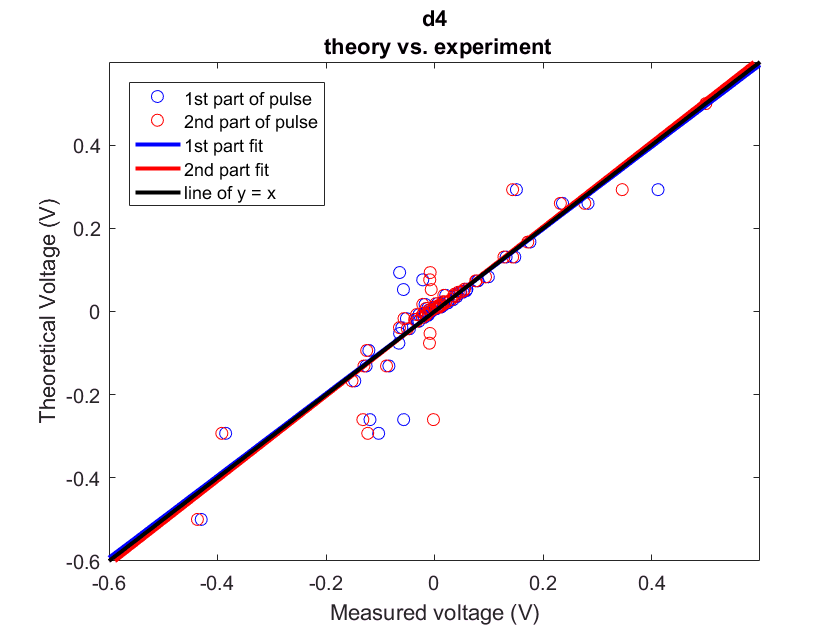

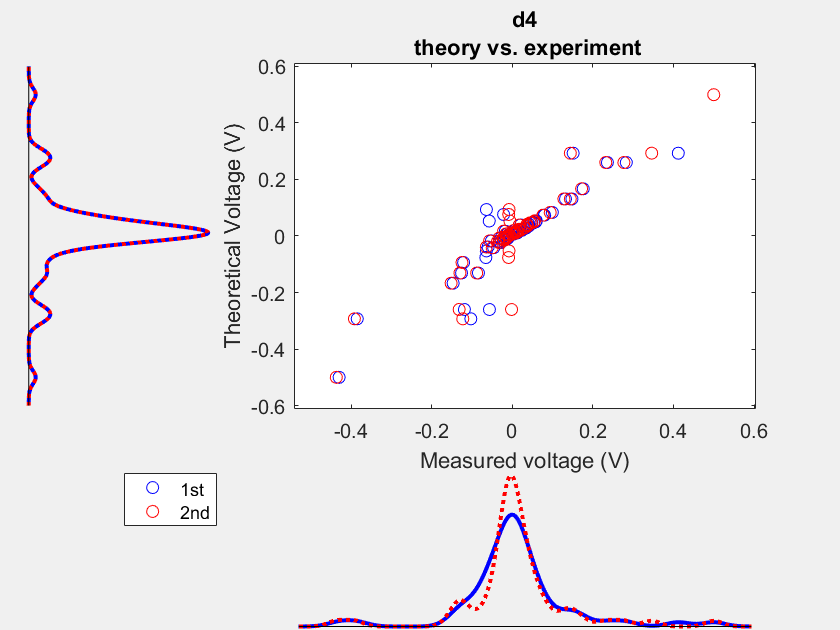

scatterplot_func(d4)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.035  (0.956, 1.114)
       p2 =   -0.009392  (-0.0178, -0.000987)

gof1_1st =            sse: 0.0591
       rsquare: 0.9196
           dfe: 60
    adjrsquare: 0.9183
          rmse: 0.0314


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.052  (0.974, 1.13)
       p2 =   -0.008004  (-0.01623, 0.0002264)

gof1_2nd =            sse: 0.0563
       rsquare: 0.9235
           dfe: 60
    adjrsquare: 0.9223
          rmse: 0.0306


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.035  (0.956, 1.114)
       p2 =   -0.009392  (-0.0178, -0.000987)

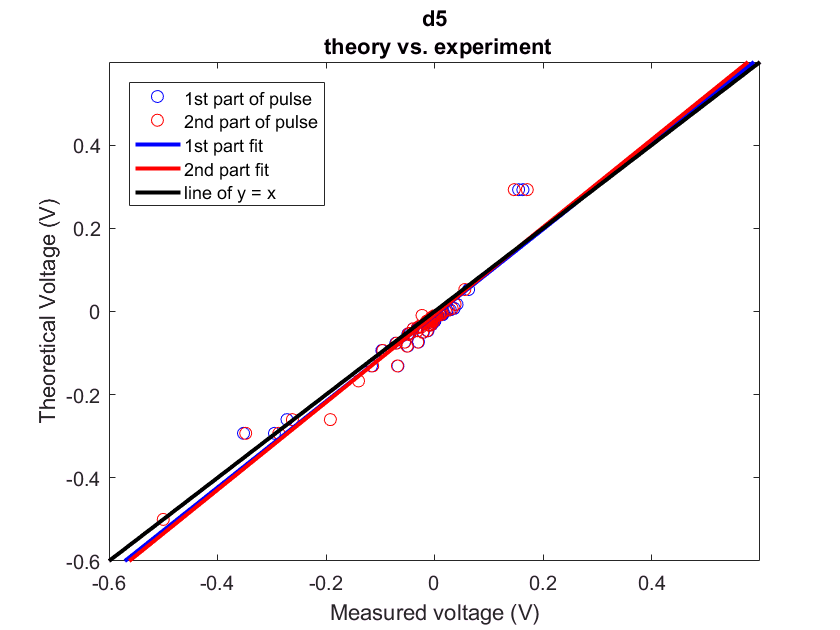

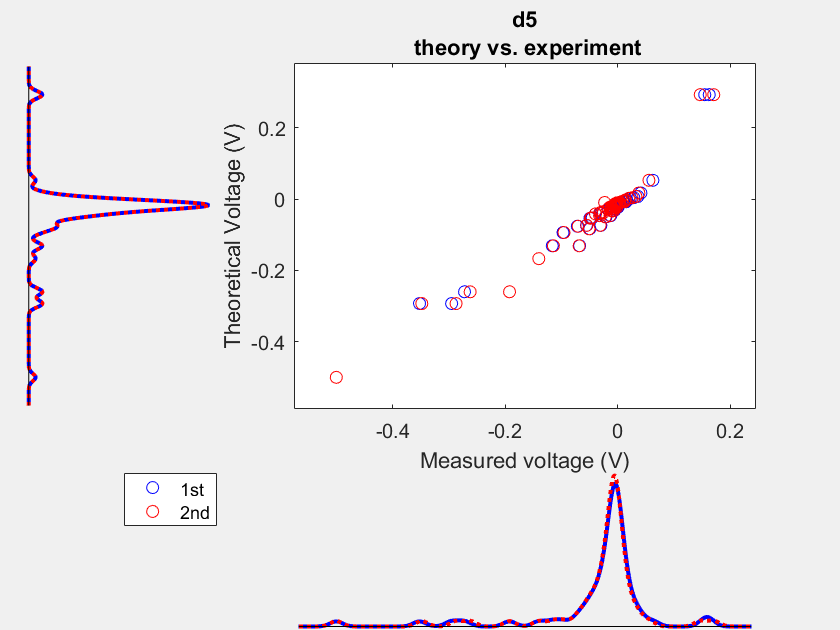

scatterplot_func(d5)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.077  (0.9991, 1.154)
       p2 =   -0.006583  (-0.01511, 0.001941)

gof1_1st =            sse: 0.0531
       rsquare: 0.9280
           dfe: 60
    adjrsquare: 0.9268
          rmse: 0.0297


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.116  (1.028, 1.205)
       p2 =    -0.01055  (-0.02003, -0.001079)

gof1_2nd =            sse: 0.0633
       rsquare: 0.9141
           dfe: 60
    adjrsquare: 0.9127
          rmse: 0.0325


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.077  (0.9991, 1.154)
       p2 =   -0.006583  (-0.01511, 0.001941)

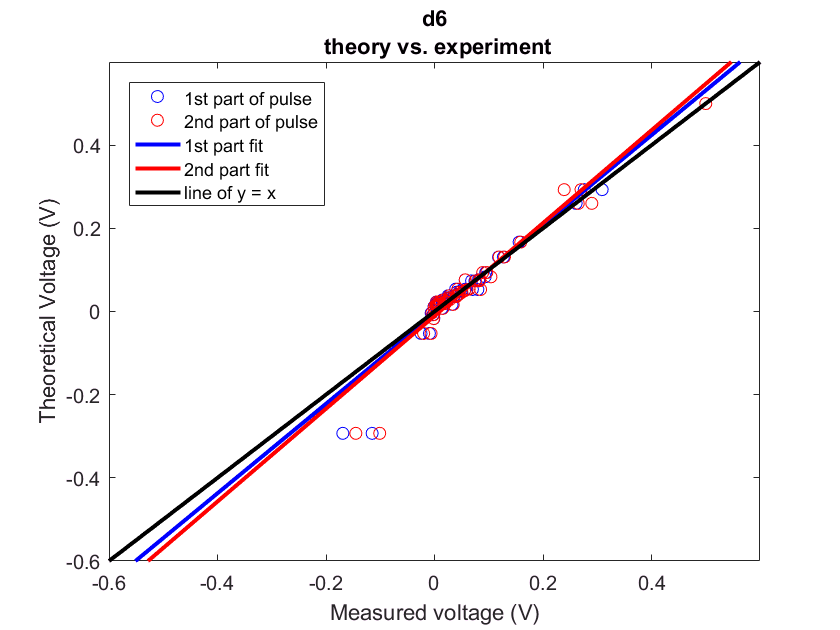

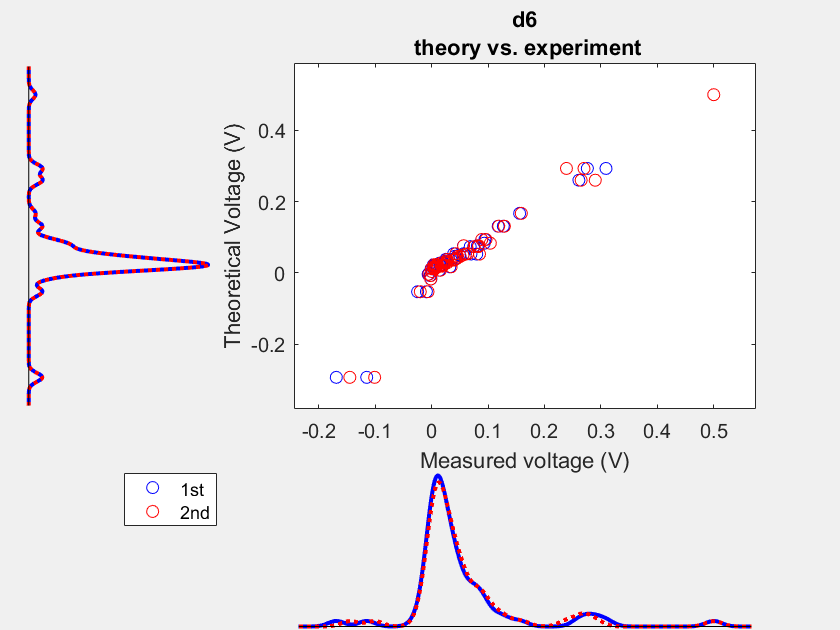

scatterplot_func(d6)

curve1_1st =      Linear model Poly1:
     curve1_1st(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9201  (0.8379, 1.002)
       p2 =     0.01217  (0.003389, 0.02095)

gof1_1st =            sse: 0.0547
       rsquare: 0.8932
           dfe: 60
    adjrsquare: 0.8914
          rmse: 0.0302


curve1_2nd =      Linear model Poly1:
     curve1_2nd(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9098  (0.8264, 0.9932)
       p2 =     0.01192  (0.002937, 0.02091)

gof1_2nd =            sse: 0.0574
       rsquare: 0.8881
           dfe: 60
    adjrsquare: 0.8862
          rmse: 0.0309


ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9201  (0.8379, 1.002)
       p2 =     0.01217  (0.003389, 0.02095)

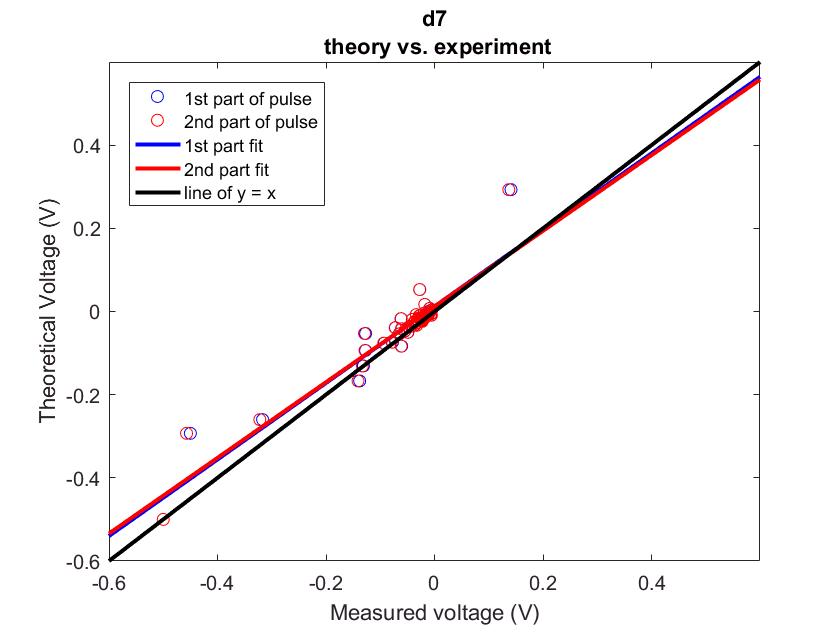

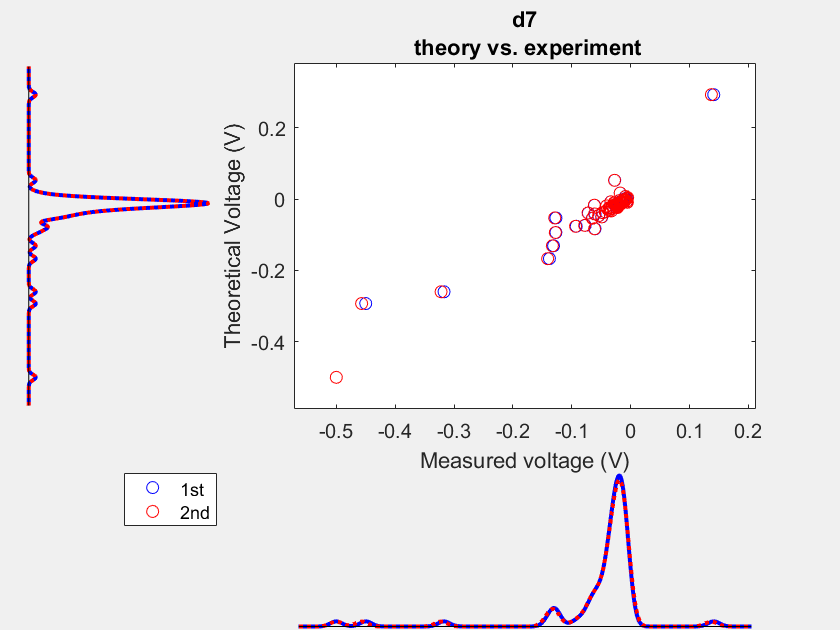

scatterplot_func(d7)